# Ejercicio tipo Examen

## 1) Ejercico Salarios

## 2) Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede exceder de 33m/s a los 4s. 


$$v=\sqrt{g\frac{m}{c_d }\;}$$

$$\mathrm{tanh}\left(\sqrt{g\frac{c_d }{m}}\right)t$$


g = 9.81;
cd = 0.25;
vMax=33;
t=4;

v=@(m) ((sqrt(g*m/cd)).*tanh(sqrt(g*cd./m)*t)-vMax)

v = function_handle with value:
    @(m)((sqrt(g*m/cd)).*tanh(sqrt(g*cd./m)*t)-vMax)


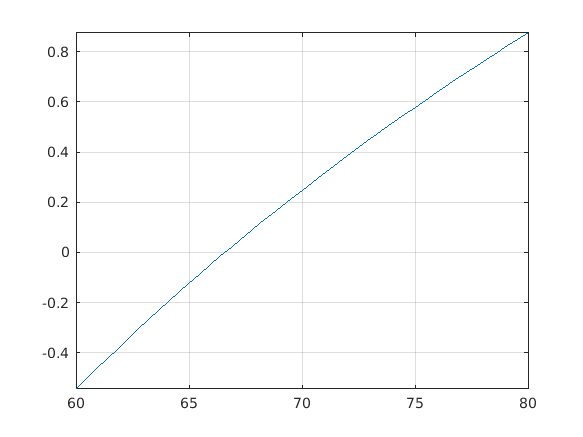

a=60;
b=80;
fplot(v,[a,b])
grid on

[x,i]=interpolacion(v,a,b)

x = 66.6000

i = 13

## 3) Principio de Arquímedes y una esfera de radio r

De acuerdo con el principio de Arquímedes, la **fuerza de flotación** es igual al **peso del fluido desplazado** por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu cálculo: r = 1m, densidad de la esfera ρe = 200kg/m3 y densidad del agua ρa= 1000kg/m3. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante

 
$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


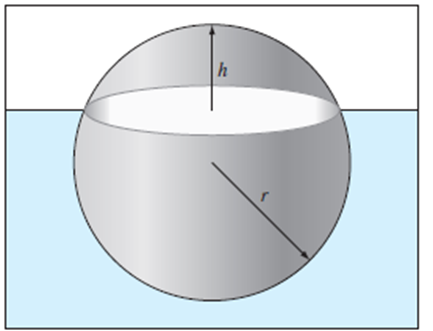

Para estar en equilibrio, la fuerza de flotación (que depende de h) debe ser igual al peso total de la esfera. Recuerda que F=mg y m=ρV. Por lo tanto, F = ρVg.

¿Peso de la esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? En equilibrio la fuerza total es cero. 

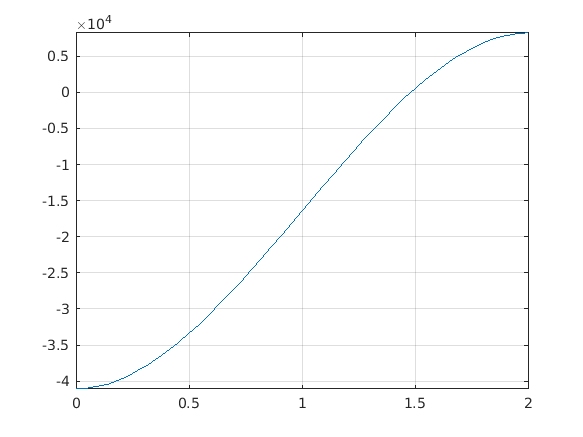

r=1;
pa=1000;
pe=200;
vTot=(4*pi*r^3)/3;
vAfuera=@(h) (pi*h.^2/3).*(3*r-h);
fGrav= @(h) pe*g.*vAfuera(h);
fFlot= @(h) g*pa.*(vTot-vAfuera(h));

f= @(h) fGrav(h)-fFlot(h);
a=0;
b=2*r;
fplot(f,[a,b])
grid on

[res3,i3]=biseccion(f,a,b)

res3 = 1.4817

i3 = 52